addpath(genpath('../'))
set(0,'DefaultFigurePosition',[1200 800 580 406])
clear all
close all
clc

% load('datasets/log2D_N4000_nu0.mat'); extrinsic_nz=10^(-1);
load('datasets/log2D_N4000.mat'); extrinsic_nz = 0;

## compute approximate particle distribution (Xscell, t)

exps = 1:8;
subsampN = 1;

numx = 128 + 1;
numsdv = 3;
custdom = [];
coarsen_data = [[0 1 1];[0 1 1];[0 1 1]];
Xsnz = [extrinsic_nz 1];
scoord = 0;

NN = size(Xscell{1},1);
dim = size(Xscell{1},2)+1;

get_particle_distrib;

ET_load_data = 0.7082 


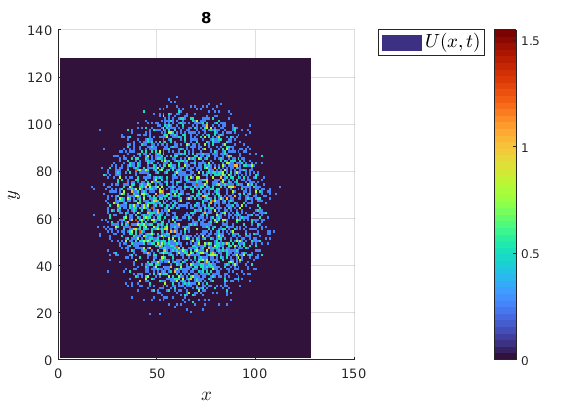

plotgap=1;
plot_distrib;

## choose model library

% local autonomous operators
max_dx = 0;
max_dt = 0;
polys = [];
trigs = [];
use_all_dt = 0;
use_cross_dx = 0;
custom_add = [];
custom_remove = {@(mat,lhs) find(all([mat(:,2)==0 mat(:,3)==0 ~ismember(mat,lhs,'rows')],2))};
toggle_comb = 1;

% local non-autonomous operators
driftpolys=[0:5]; drifttrigs=[];
diffpolys=[]; difftrigs=[0:2]; crossdrift=1;

% non-local operators
convargs = {{'dimx',dim-1,'utagin',1,'utagout',1,'psitags',1,'Mon',[1:5],'Sing',[-1:0.5:0],'Exp',[],'Singeps',[0.01],'svdtol',[1e-4]}};

set_library;

ET_build_lib = 1.4065 


## Set Discretization

phi_class = {1,1};
sm_x = 3;
sm_t = 5;

## uncomment to set test fcn params manually

p_x = 5; mxs = 25;
tau_x = []; k_x = []; tauhat_x = []; 
p_t = 3; mts = 8;
tau_t = []; k_t = []; tauhat_t = [];

% %%% set test fcn params using cornerpoint
% tauhat_x = 0.5; tau_x = 10^-6;
% p_x = []; mxs = 1;
% tauhat_t = 0.3; tau_t = 10^-3;
% p_t = []; mts = 1;

## rescale coordinates and/or use approx. variance for improved conditioning

scales = 2;
covtol = 0;

## trim rows with low particle density

trim_tags = [1 zeros(1,dim-1) 0];
trim_fcn = {@(col) max(col/max(abs(col)),eps)};
inds_keep_fcn = @(col) log10(col)>-inf;

set_discretization;

ET_setdisc = 1.3959 


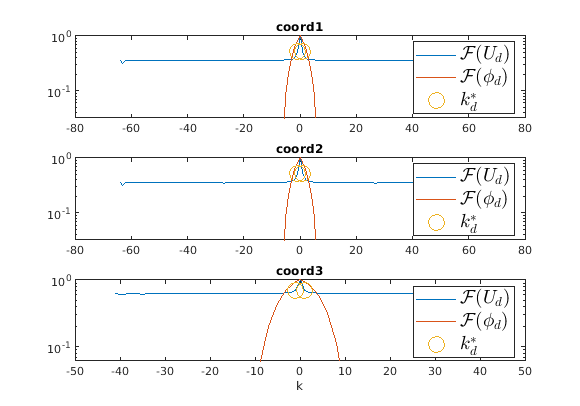


toggle_plot_fft = 1;
plot_Ufft;

## Build linear systems

build_Gb;

ET_build_Gb = 6.1824 


## MSTLSQP

lambda = 10.^(linspace(-4, 0, 100));
gamma_tol = Inf;
alpha = 0.5;
maxits = Inf;
sparsity_scale = 0;
excl_tags={'u^{1}_{lap}','u^{1}_{xx}','([x.^0.*t.^0]u^1)_{xx}','([x.^0.*y.^0.*t.^0]u^1)_{lap}'};
excl_tols=0;
tol = 10^-8; 
maxQPits = 100; 
dispQP = 'off';
meth = 'STLSQP';

sparsereg_script;

ET_solve_sparse_reg = 2.1942 


## get_results

print_loc = 1;
warning('off','MATLAB:dispatcher:UnresolvedFunctionHandle')
get_results;


Recovered PDE: u^{1}_{t} = 0.15834convsing-1
Relative Res: ||b-G*W||_2/||b||_2 = 1.89e-01
Max Weight Error: max|W-W_{true}| = 5.12e-03
TP Score = 1.00
      
polys = 1 
trigs =  
Max derivs [t x] = 1 2 
[m_x m_t] = 25 8 
[s_x s_t] = 8 1 
[p_x p_t] = 5 3 
 scales = 1.00e+00 4.06e+00 4.06e+00 1.25e+00 
      
Total particles = 4000 
Size of U = 128 128 81 
Size G = 6500 53 
Cond G = 2.41e+06
[lambda_hat gamma] = 1.385e-02 0.000e+00 
extrinsic noise ratio= 1.000e-01
STLS its = 5 
total elapsed time = 11.6282 


## Display loss

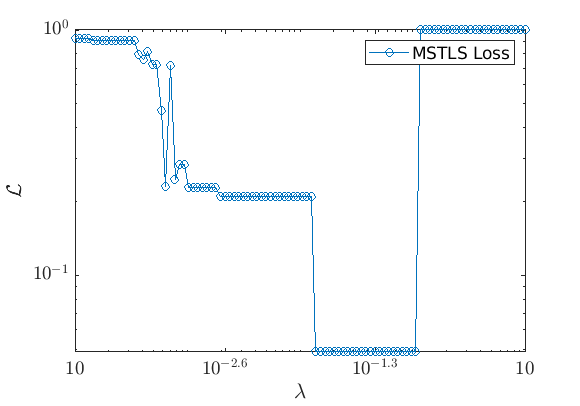

toggle_plot_loss = 1;
plot_loss;

## Display drift/diffusion

toggle_plot_drift = 0;
plot_driftdiff;

## Display interaction force

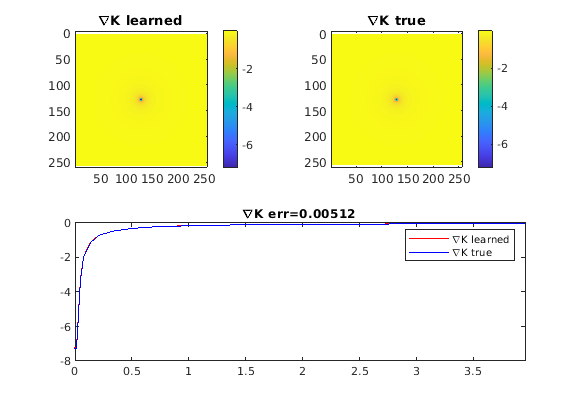

toggle_plot_IPforce = 1;
plot_K